load('res_data.mat');

% 交换顺序
outlist1{1} = outlist{1};
outlist1{2} = outlist{4};
outlist1{3} = outlist{2};
outlist1{4} = outlist{5};
outlist1{5} = outlist{3};
outlist1{6} = outlist{6};
outlist = outlist1

outlist = 1×6 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


bc = 10;
colorset = ['#5ADC98';'#985ADC';'#a93226';'#F4D03F';'#16A085';'#4E56E2'];

close(figure(1));
figure(1);
grid on
hold on
t_len = 0;
for i = 1:2
    y = outlist{i};
    U = y.U;
    t = 1:size(U,2);
    t_len = max(t_len, size(U,2))
    plot(t,U,'-','LineWidth',1.8,...
        'Color',colorset(i,:));
end

t_len = 2881

t_len = 2881

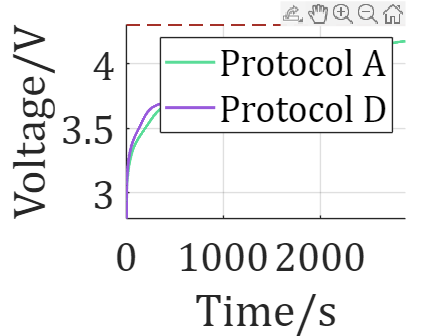

% xlim([0 650]);
% ylim([3.4,4.4]);
plot(1:t_len,ones(t_len,1)*4.3,'--','LineWidth',1,...
    'Color','#98140A');
hold off
legend('Protocol A','Protocol D');
xlabel('Time/s');ylabel('Voltage/V');
set(gca,'fontname','Cambria','fontsize',25);

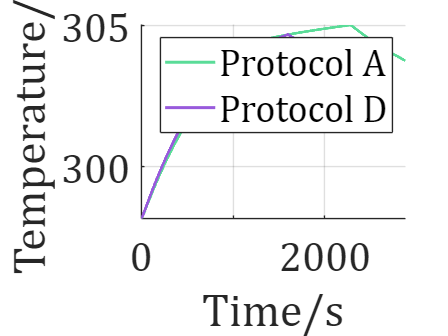

close(figure(2));
figure(2);
grid on
hold on
for i = 1:2
    y = outlist{i};
    T = y.T;
    t = 1:size(T,2);
    plot(t,T,'-','LineWidth',1.8,...
        'Color',colorset(i,:));
end
legend('Protocol A','Protocol D');
hold off
xlabel('Time/s');ylabel('Temperature/K');
set(gca,'fontname','Cambria','fontsize',25);

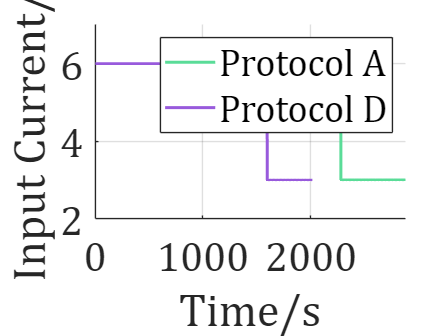

close(figure(3));
figure(3);
grid on
hold on
colorcube(6);
for i = 1:2
    y = outlist{i};
    I = y.I;
    t = 2:size(I,2);
    plot(t,I(1,2:end),'-','LineWidth',1.8,...
        'Color',colorset(i,:));
end
ylim([2,7]);
legend('Protocol A','Protocol D');
xlabel('Time/s');ylabel('Input Current/A');
set(gca,'fontname','Cambria','fontsize',25);

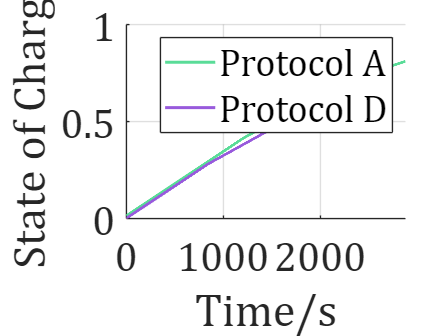

close(figure(4));
figure(4);
grid on
hold on
for i = 1:2
    y = outlist{i};
    sei = y.soc;
    t = 1:size(sei,2);
    plot(t,sei,'-','LineWidth',1.8,...
        'Color',colorset(i,:));
end
legend('Protocol A','Protocol D');
xlabel('Time/s');ylabel('State of Charge');
set(gca,'fontname','Cambria','fontsize',25);

close(figure(1));
figure(1);
grid on
hold on
t_len = 0;
for i = 3:6
    y = outlist{i};
    U = y.U;
    t = 1:size(U,2);
    t_len = max(t_len, size(U,2))
    plot(t,U,'-','LineWidth',2,...
        'Color',colorset(i,:));
end

t_len = 7201

t_len = 7201

t_len = 7201

t_len = 7201

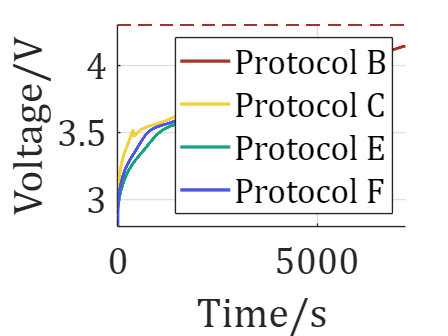

plot(1:t_len,ones(t_len,1)*4.3,'--','LineWidth',1,...
    'Color','#98140A');
hold off
legend('Protocol B','Protocol C','Protocol E','Protocol F');
xlabel('Time/s');ylabel('Voltage/V');
set(gca,'fontname','Cambria','fontsize',23);

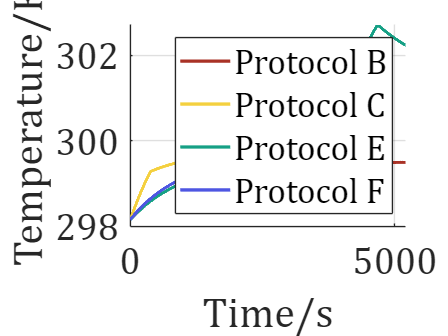

close(figure(2));
figure(2);
grid on
hold on
for i = 3:6
    y = outlist{i};
    T = y.T;
    t = 1:size(T,2);
    plot(t,T,'-','LineWidth',2,...
        'Color',colorset(i,:));
end
xlim([0,5200]);
legend('Protocol B','Protocol C','Protocol E','Protocol F');
xlabel('Time/s');ylabel('Temperature/K');
set(gca,'fontname','Cambria','fontsize',23);

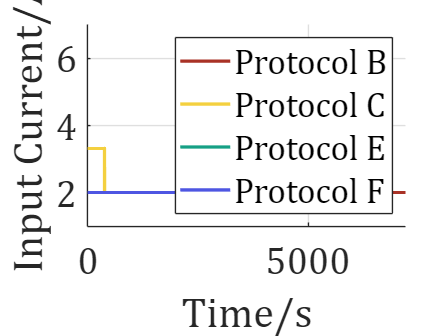

close(figure(3));
figure(3);
grid on
hold on
for i = 3:6
    y = outlist{i};
    I = y.I;
    t = 2:size(I,2);
    plot(t,I(1,2:end),'-','LineWidth',2,...
        'Color',colorset(i,:));
end
ylim([1,7]);
legend('Protocol B','Protocol C','Protocol E','Protocol F');
xlabel('Time/s');ylabel('Input Current/A');
set(gca,'fontname','Cambria','fontsize',23);

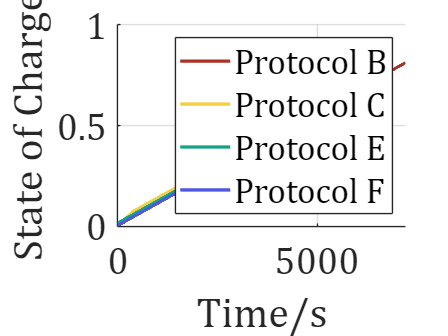

close(figure(4));
figure(4);
grid on
hold on
for i = 3:6
    y = outlist{i};
    sei = y.soc;
    t = 1:size(sei,2);
    plot(t,sei,'-','LineWidth',2,...
        'Color',colorset(i,:));
end
legend('Protocol B','Protocol C','Protocol E','Protocol F');
xlabel('Time/s');ylabel('State of Charge');
set(gca,'fontname','Cambria','fontsize',23);

% OptimalProtocol(:,8) = OptimalProtocol(:,8)/(4608000000*96485*55e-6)